clear all;
R1_v = 1e3; R2_v = 2e3;
R3_v = 1e3; Rx_v = 3e3;
V0_v = 5;
syms R1 R2 R3 Rx V0
syms r;
I = V0 * (R2 * R3 - R1 * Rx) / (R1*Rx*R3 + R2*Rx*R3 + R1*R2*Rx + R1*R2*R3)

$$I = \frac{V_{0}\,\left(R_{2}\,R_{3}-R_{1}\,\mathrm{Rx}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,\mathrm{Rx}+R_{1}\,R_{3}\,\mathrm{Rx}+R_{2}\,R_{3}\,\mathrm{Rx}}$$

I_r = V0 * (R2 * R3 - R1 * Rx) / ...
    (r*R1*R3 + r*R2*R3 + R1*R2*R3 + R1*Rx*R3 + R2*Rx*R3 + r*R1*Rx + r*R2*Rx + R1*R2*Rx)

$$I\_r = \frac{V_{0}\,\left(R_{2}\,R_{3}-R_{1}\,\mathrm{Rx}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,\mathrm{Rx}+R_{1}\,R_{3}\,\mathrm{Rx}+R_{2}\,R_{3}\,\mathrm{Rx}+R_{1}\,R_{3}\,r+R_{2}\,R_{3}\,r+R_{1}\,\mathrm{Rx}\,r+R_{2}\,\mathrm{Rx}\,r}$$

limit(I_r, r, 0)

$$ans = \frac{V_{0}\,\left(R_{2}\,R_{3}-R_{1}\,\mathrm{Rx}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,\mathrm{Rx}+R_{1}\,R_{3}\,\mathrm{Rx}+R_{2}\,R_{3}\,\mathrm{Rx}}$$

latex(I)

ans = '\frac{V_{0}\,\left(R_{2}\,R_{3}-R_{1}\,\mathrm{Rx}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,\mathrm{Rx}+R_{1}\,R_{3}\,\mathrm{Rx}+R_{2}\,R_{3}\,\mathrm{Rx}}'

latex(I_r)

ans = '\frac{V_{0}\,\left(R_{2}\,R_{3}-R_{1}\,\mathrm{Rx}\right)}{R_{1}\,R_{2}\,R_{3}+R_{1}\,R_{2}\,\mathrm{Rx}+R_{1}\,R_{3}\,\mathrm{Rx}+R_{2}\,R_{3}\,\mathrm{Rx}+R_{1}\,R_{3}\,r+R_{2}\,R_{3}\,r+R_{1}\,\mathrm{Rx}\,r+R_{2}\,\mathrm{Rx}\,r}'

fewre

tmp = I_r;
tmp = subs(tmp, R1, R1_v);
tmp = subs(tmp, R2, R2_v);
tmp = subs(tmp, R3, R3_v);
tmp = subs(tmp, Rx, Rx_v);
tmp = subs(tmp, V0, V0_v);
f_Ir = tmp

$$f\_Ir = -\frac{5000000}{12000000\,r+17000000000}$$

plot

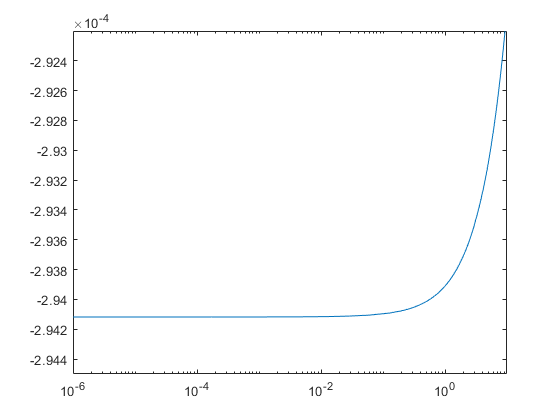

fplot(f_Ir, [1e-6, 10])
set(gca, "XScale", "log")
set(gca, "Ylim", [-2.945, -2.922]*1e-4)

10%

I_0 = subs(f_Ir, r, 0);

Array indices must be positive integers or logical values.

Error in sym/subsref (line 907)
            R_tilde = builtin('subsref',L_tilde,Idx);

I_1 = I_0 * 0.9;
solve(f_Ir - I_1, r)